# Measurement data of OL490 simulating CIE illuminants on 6/17/2022, 62/3133 (HIMS2)

For LightSim paper, 12/1/2022

Q: How to evaluate like Tommy Wei's and Ling Ma's papers

A: SAM

## Reference data

CIE D: my class based on formula

CIE F: my class based on Excel data

CIE A: from "C:\Users\wayne\Documents\GitHub\lightmatching\datain" (9/24/2015)

CIE E: my creation

load myCIEtest12142022

## Show CIE D findings

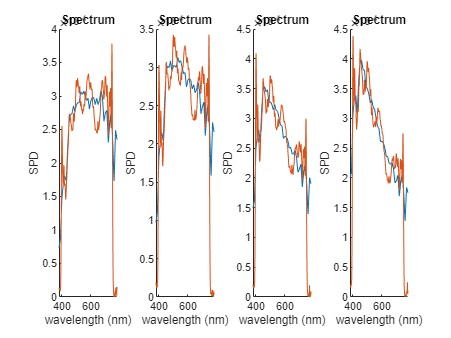

clf

tiledlayout(1,4,'TileSpacing','compact')

nexttile(1)
hold on
plot(380:780,spec_d50)
mea_d50.plot

nexttile(2)
hold on
plot(380:780,spec_d55)
mea_d55.plot

nexttile(3)
hold on
plot(380:780,spec_d65)
mea_d65.plot

nexttile(4)
hold on
plot(380:780,spec_d75)
mea_d75.plot

## Combine D 

12/4/2022

mea16 = zeros(4,401);
ref16 = zeros(4,401);
name16 = {};

%
% D50
%
i = 1;
mea16(i,:) = mea_d50.amplitude;
ref16(i,:) = speC_d50.amplitude*sc;
name16{i} = 'D50';

%
% D55
%
i = 2;
mea16(i,:) = mea_d55.amplitude;
ref16(i,:) = speC_d55.amplitude*sc;
name16{i} = 'D55';

%
% D65
%
i = 3;
mea16(i,:) = mea_d65.amplitude;
ref16(i,:) = speC_d65.amplitude*sc;
name16{i} = 'D65';

%
% D75
%
i = 4;
mea16(i,:) = mea_d75.amplitude;
ref16(i,:) = speC_d75.amplitude*sc;
name16{i} = 'D75';


## Normalize data

% ref16 = ref16 ./ sum(ref16,2);
% mea16 = mea16 ./ sum(mea16,2);

## Generate plot

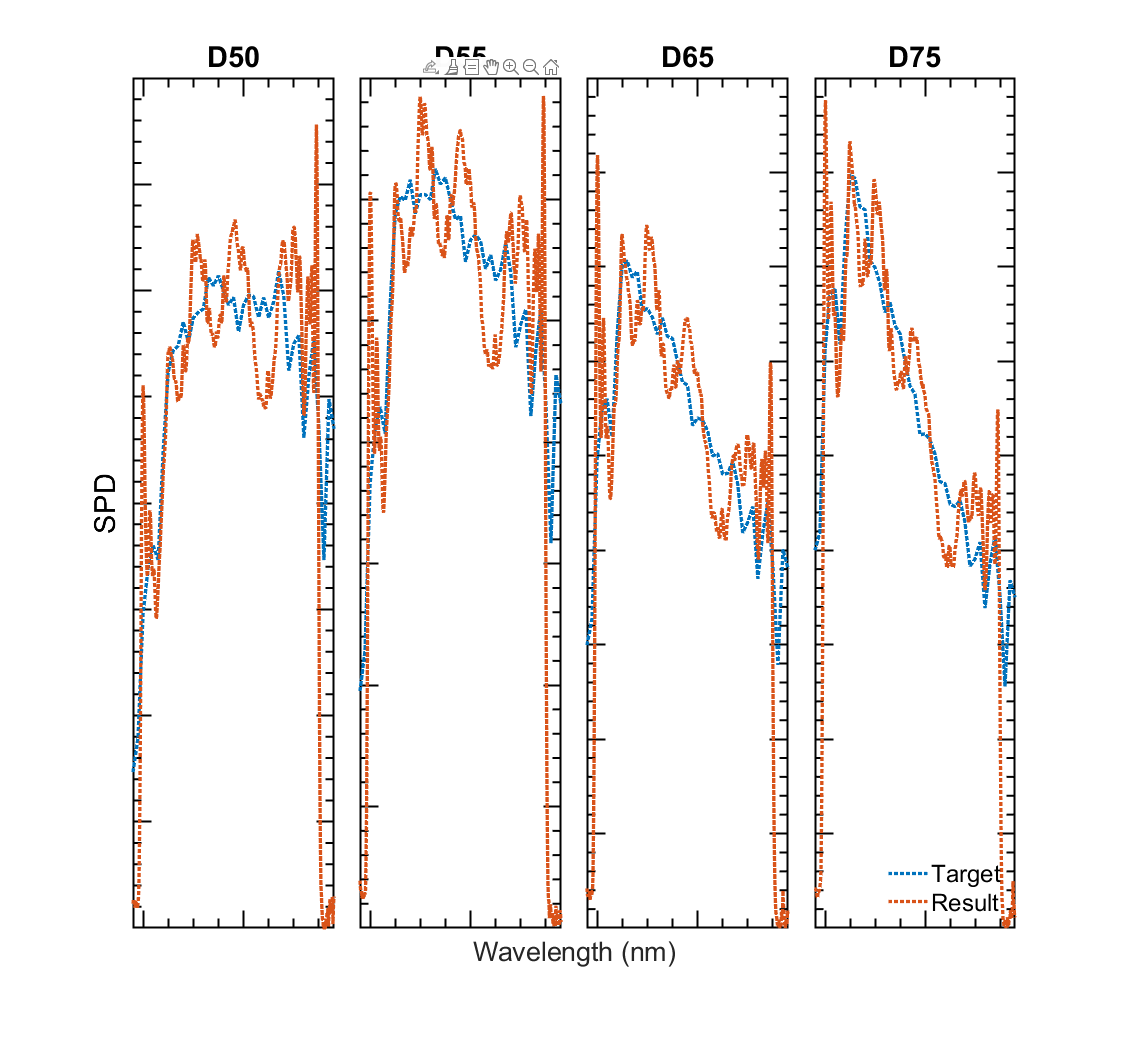

clf
td = tiledlayout(1,4,'TileSpacing','compact');
hg = gcf;
set(hg,'Visible','on');
for idx = 1:4
    haxis = nexttile(idx);
    hold on
    plot(380:780,ref16(idx,:),':')
    plot(380:780,mea16(idx,:),':')
    title(name16{idx})
    xticklabels({});
    yticklabels({});
    PlotBeautify(haxis)
    legend off

    if idx < 9
        xticklabels({});
    end

    yticklabels({});

    if mod(idx,4)==1
        ylabel('SPD');
    end

    switch idx
        case 4
            lgd = legend('Target','Result','Location','southeast');
            lgd.Box = 'off';
    end
end
td.XLabel.String = 'Wavelength (nm)';
td.XLabel.FontSize = 20;

hg.Position = [579 57 1122 1043];
saveas(hg,'spectrum16.png')

## PSNR, SAM, and CIE u'v' evaluation

ISO 23603 criterion is du'v' < 0.015

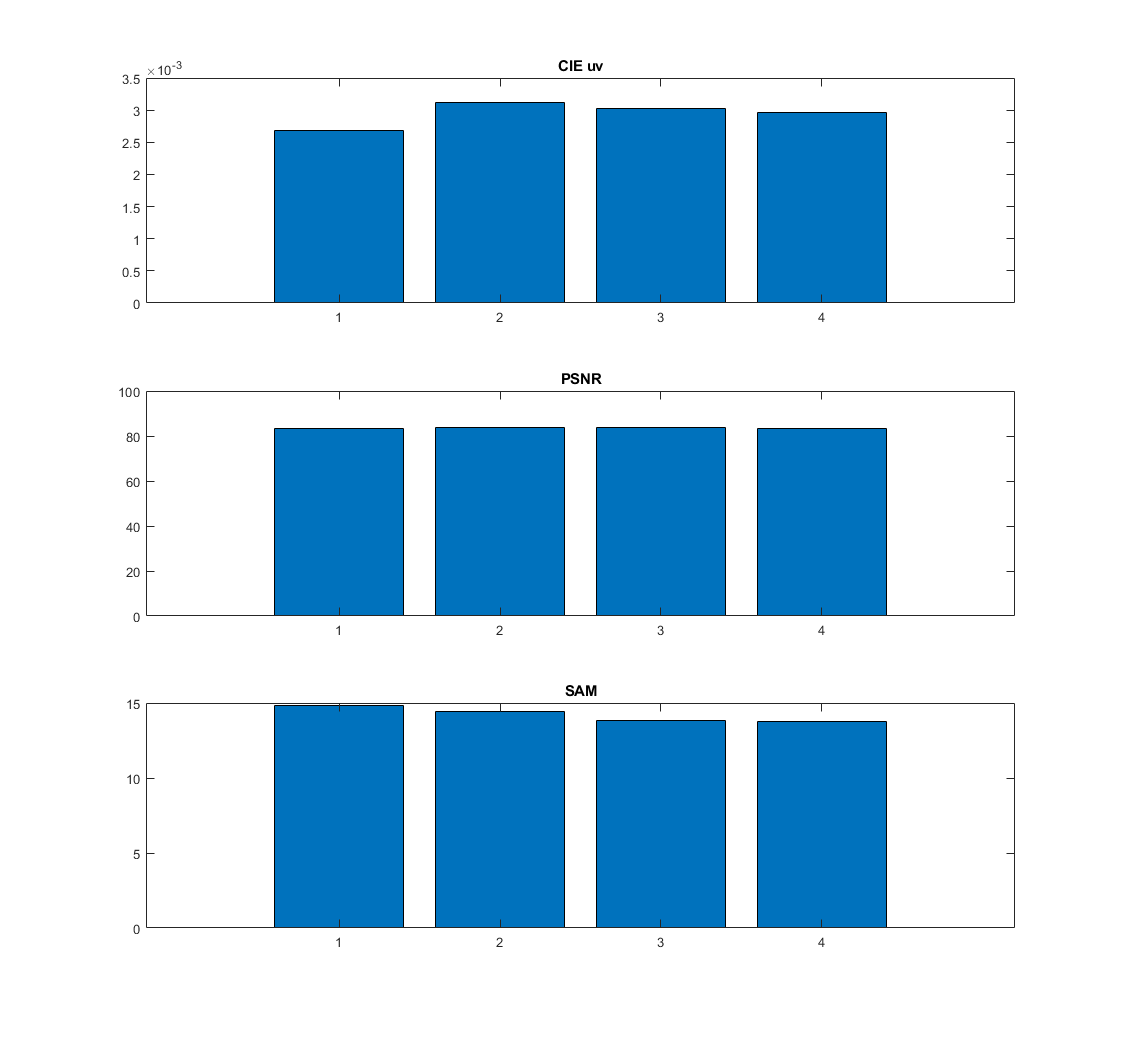

duv16 = zeros(4,1);
sam16 = zeros(4,1);
psnr16 = zeros(4,1);

for i=1:4
    spec_ref = ref16(i,1:10:401)';
    spec_mea = mea16(i,1:10:401)';
    duv16(i,1) = ColorConversionClass.spd2duv(spec_ref,spec_mea);
    sam16(i,1) = rad2deg(sam(spec_ref,spec_mea));
    psnr16(i,1) = psnr(spec_ref,spec_mea);
end

clf
subplot(3,1,1); bar(duv16); title('CIE uv')
subplot(3,1,2); bar(psnr16); title('PSNR')
subplot(3,1,3); bar(sam16); title('SAM')


eva_table = table(psnr16, sam16, duv16,'VariableNames',{'PSNR','SAM','du''v'''},'RowName',name16)

eva_table = 4×3 table
            PSNR      SAM        du'v'  
           ______    ______    _________

    D50    83.404    14.859    0.0026837
    D55    83.709    14.407    0.0031201
    D65    83.811    13.861     0.003018
    D75    83.515    13.797    0.0029651


Matlab2latex.table2latex(eva_table)